# Process ImageJ Data

This script creates a file "RawF.txt" that is a processed version of the ImageJ output file "Results.txt". There are two steps:

- Resample data at 5 Hz (up from ~3.79 Hz)

- Add stimulus information such as the trial number and grating orientation.

## Resample data

The raw data file has 2184 rows, which are different frames collected over a period of 576 seconds. This means the data was sampled at 2184/576 $\approx$ 3.79 Hz.We will resample this data at 5 Hz so there's an even number of frames for each stimulus. 

% Define constants
totalTime = 576; % seconds
frameRate = 5; % Hz
numSamples = 2184;
numCells = 73;

% Read in data as a timetable. Rename vars to use "Cell" instead of "Var"
rawF = readtimetable("Results.txt","Range","B2","SampleRate",numSamples/totalTime);

% Resample at 5 Hz. Use a smooth type of interpolation ("makima")
rawF = retime(rawF,"regular","makima","SampleRate",frameRate);

% Convert to regular table and clean up variables
rawF = timetable2table(rawF);
rawF = removevars(rawF,"Time");
rawF = renamevars(rawF,"Var" + (1:numCells),"Cell" + (1:numCells))

rawF = 2880×73 table
    Cell1     Cell2     Cell3     Cell4     Cell5     Cell6     Cell7     Cell8     Cell9     Cell10    Cell11    Cell12    Cell13    Cell14    Cell15    Cell16    Cell17    Cell18    Cell19    Cell20    Cell21    Cell22    Cell23    Cell24    Cell25    Cell26    Cell27    Cell28    Cell29    Cell30    Cell31    Cell32    Cell33    Cell34    Cell35    Cell36    

## Add stimulus information

The stimulus variables will allow keep track of the experimental parameters to simplify our analysis. For example, say we have two trials in an experiment and a stimulus that cycles ON and OFF. We could arrange a table like this:


$$\begin{array}{llll}
Trial & Cycle & Cell1 & Cell2 \\
1     & \text{OFF} & 0.82  & 0.93  \\
1     & \text{OFF} & 0.91  & 0.63  \\
1     & \text{ON} & 0.13  & 0.10  \\
1     & \text{ON} & 0.17  & 0.09  \\
2     & \text{OFF} & 0.66  & 0.82  \\
2     & \text{OFF} & 0.71  & 0.63  \\
2     & \text{ON} & 0.03  & 0.31  \\
2     & \text{ON} & 0.05  & 0.28 
\end{array}$$


The $Trial$ and $Cycle$ columns are the grouping variables that will help us keep track of each observation.

For this experiment, the stimuli are slightly more complicated. Drifting gratings at **12** different orientations are presented. The stimuli are presented in order (0°, 30°, 60°, etc), with each stimulus ON for **4** seconds, and each preceded by a **4** second OFF period. This whole sequence is repeated **6 **times.

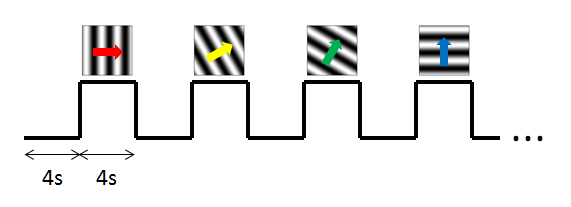

Therefore, we will ceate four stimulus variables: `Trial`, `Time`, `Orientation`, and `Cycle`.

- `Trial` - Trial identifier, so integers from 1 to 6

- `Time` - Time in seconds within a trial, so values from 0 to 96 in steps of 0.2 (5 Hz)

- `Orientation` - Grating rotation in degrees, so integers like 0, 30, 60, etc..

- `Cycle` - String values of "ON", OFF" that labels when the stimulus was on or off. The period directly after the stimulus turned off is ignored and left blank with an empty set of quotes "". For example, in the data shown below, the times marked with the green line will have the label "ON", while the red times will have the label "OFF". 

 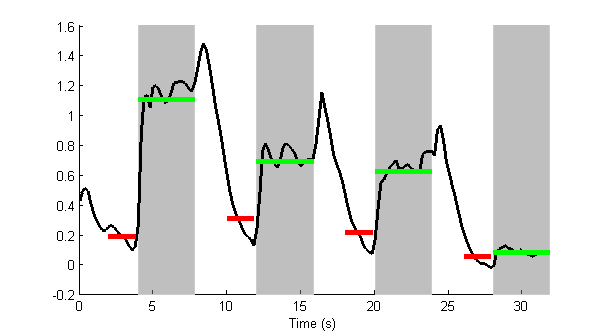

% Define stimulus parameters
orientations = 0:30:330; % degrees
trials = 1:6;
numStimuli = length(orientations);
numTrials = length(trials);

% Get number of samples per trial and stimulus
samplesPerTrial = totalTime*frameRate/numTrials;
samplesPerStimulus = samplesPerTrial/numStimuli;

% Trial group: Label each sample by the trial (1:6)
trialGroup = repelem(trials',samplesPerTrial);

% Time group: 6 repetions of a time vector (1 for each trial)
trialTime = (0:samplesPerTrial-1)'/frameRate;
timeGroup = repmat(trialTime,numTrials,1);

% Stimulus group, repetitions of 0:30:330 (orientation degrees)
singleStimulus = repelem(orientations',samplesPerStimulus);
stimulusGroup = repmat(singleStimulus,numTrials,1);

% Cycle group, repetitions of "","OFF","ON".
cycles = ["";"OFF";"ON";"ON"];
singleStimulus = repelem(cycles,samplesPerStimulus/length(cycles));
singleTrial = repmat(singleStimulus,numStimuli,1);
cycleGroup = repmat(singleTrial,numTrials,1);

% Add the grouping variables to the table
rawF.Time = timeGroup;
rawF.Trial = trialGroup;
rawF.Orientation = stimulusGroup;
rawF.Cycle = cycleGroup;
rawF = movevars(rawF,["Trial","Time","Orientation","Cycle"],"before","Cell1")

rawF = 2880×77 table
    Trial    Time    Orientation    Cycle    Cell1     Cell2     Cell3     Cell4     Cell5     Cell6     Cell7     Cell8     Cell9     Cell10    Cell11    Cell12    Cell13    Cell14    Cell15    Cell16    Cell17    Cell18    Cell19    Cell20    Cell21    Cell22    Cell23    Cell24    Cell25    Cell26    Cell27    Cell28    Cell29    Cell30    Cell31    Cell32    <s

## Visualize stimulus variables

As a sanity check, we can visualize the stimulus variables with a function called `stackedplot`. The `Cycle` variable needs to be a "categorical" variable for this plot function, so it's converted first.

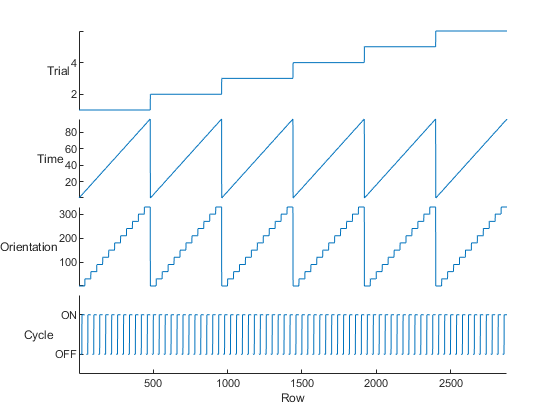

stimInfo = rawF(:,1:4);
stimInfo.Cycle = categorical(stimInfo.Cycle);
stackedplot(stimInfo)

We can also look at one trial in more detail

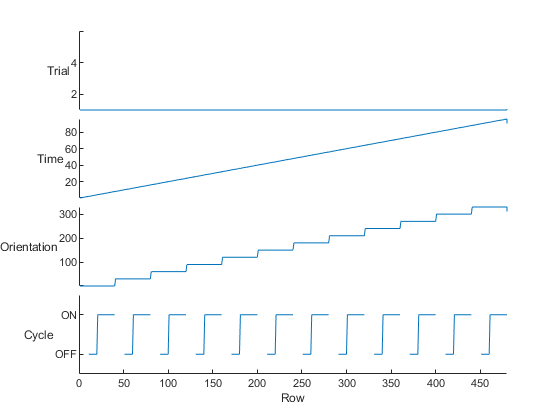

stackedplot(stimInfo)
xlim([0 samplesPerTrial])

## Write table to text file

The last step is to save a new text file with the processed data

writetable(rawF,"RawF.txt")